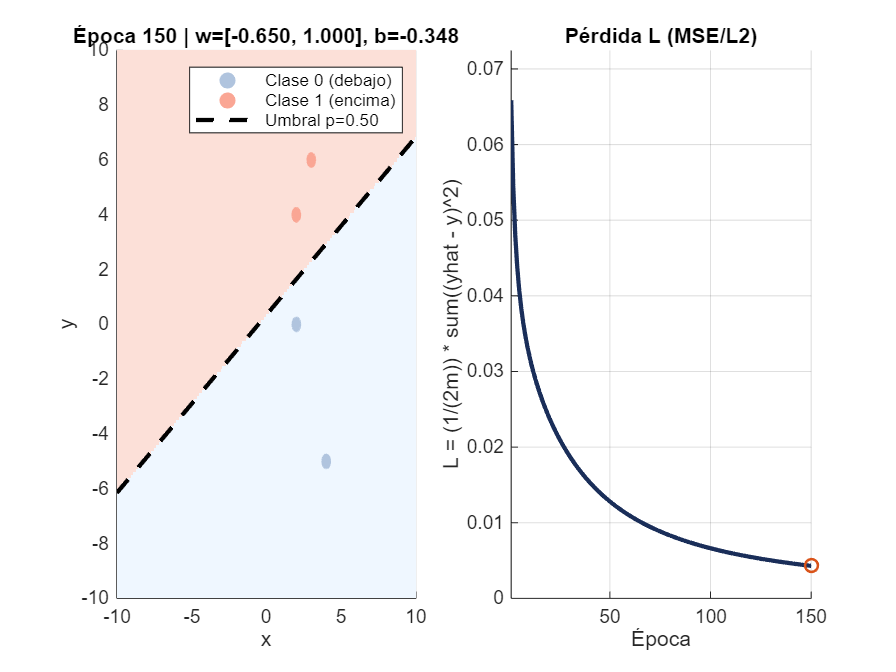

clear; clc; close all;

%% =========================
%  Perceptrón 2D con sigmoide
%  (Ejercicio: recta que separa dos clases)
%  Puntos "por encima"  -> clase 1 (verde)
%  Puntos "por debajo"  -> clase 0 (azul)
%% =========================

%% Datos (X,y) del enunciado
X = [2  4;
     3  6;
     2  0;
     4 -5];            % m x 2
y = [1; 1; 0; 0];      % m x 1
m = size(X,1);

%% Hiperparámetros
eta    = 0.25;
epochs = 150;

%% Inicialización (reproducible)
rng(0);
w = 0.1*randn(2,1);
b = 0;

%% Funciones
sigmoid = @(z) 1 ./ (1 + exp(-z));

%% Historial de pérdida
loss_hist = zeros(epochs,1);

%% Colores (puntos más oscuros; fondo más claro)
c0_pt = [0.69, 0.77, 0.87];   % azul (clase 0)
c1_pt = [0.98 0.65 0.58];   % salmon (clase 1)

c0_bg = [0.94, 0.97, 1.0];
c1_bg = [0.99, 0.88, 0.85];

% Colormap azul->verde (solo claros)
nC = 256;
cmap = [linspace(c0_bg(1), c1_bg(1), nC)', ...
        linspace(c0_bg(2), c1_bg(2), nC)', ...
        linspace(c0_bg(3), c1_bg(3), nC)'];

%% Rango de ejes (20x20)
gridMinX = -10;  gridMaxX = 10;
gridMinY = -10;  gridMaxY = 10;


nGrid = 181;
gx = linspace(gridMinX, gridMaxX, nGrid);
gy = linspace(gridMinY, gridMaxY, nGrid);
[GX, GY] = meshgrid(gx, gy);
G = [GX(:), GY(:)];

%% GIF (se guarda donde está el .mlx si existe)
outDir = pwd;
try
    st = matlab.desktop.editor.getActive;
    if ~isempty(st) && isprop(st,'Filename') && ~isempty(st.Filename)
        [outDir,~,~] = fileparts(st.Filename);
    end
catch
end

gif_name = fullfile(outDir, 'goft_ej1_entrega1.gif');
delay    = 0.12;
cover_dt = 1.0;

figure('Color','w');

%% Entrenamiento + GIF
for e = 1:epochs

    % --------- Forward (en los datos) ---------
    z    = X*w + b;          % m x 1
    yhat = sigmoid(z);       % m x 1

    % --------- Pérdida (MSE/L2) ---------
    err = (yhat - y);
    L   = (1/(2*m)) * sum(err.^2);
    loss_hist(e) = L;

    % --------- Gradientes (MSE + sigmoide) ---------
    dL_dz = (1/m) * err .* yhat .* (1 - yhat);  % m x 1
    dL_dw = X' * dL_dz;                          % 2 x 1
    dL_db = sum(dL_dz);                          % escalar

    % --------- Update ---------
    w = w - eta * dL_dw;
    b = b - eta * dL_db;

    % --------- VISUALIZACIÓN ---------
    clf;

    % (1) Plano: mapa de probabilidad + puntos + umbral
    ax1 = subplot(1,2,1); hold(ax1,'on'); grid(ax1,'on');

    % Mapa de probabilidad en la malla
    pG = sigmoid(G*w + b);
    PG = reshape(pG, nGrid, nGrid);

    % Contorno relleno (probabilidades)
    % Fondo a 2 colores (sin degradado) según umbral
    umbral = 0.5;                      % (usa el mismo que para la recta)
    C = double(PG >= umbral);          % 0 ó 1
    
    imagesc(ax1, gx, gy, C);           % pinta 2 regiones
    set(ax1,'YDir','normal');          % para que no se invierta el eje Y
    colormap(ax1, [c0_bg; c1_bg]);     % SOLO dos colores
    caxis(ax1, [0 1]);                 % fija el mapeo 0->c0_bg, 1->c1_bg



    % Puntos (círculos en unidades de datos: diámetro ~ 1)
    diam = 0.5;
    idx0 = (y==0);
    idx1 = (y==1);

    for k = find(idx0)'
        drawDataCircle(ax1, X(k,1), X(k,2), diam, c0_pt);
    end
    for k = find(idx1)'
        drawDataCircle(ax1, X(k,1), X(k,2), diam, c1_pt);
    end

    % Handles "limpios" para la leyenda
    h0 = plot(ax1, NaN, NaN, 'o', ...
        'MarkerFaceColor', c0_pt, 'MarkerEdgeColor', c0_pt, ...
        'MarkerSize', 7, 'LineStyle','none', 'DisplayName','Clase 0 (debajo)');
    h1 = plot(ax1, NaN, NaN, 'o', ...
        'MarkerFaceColor', c1_pt, 'MarkerEdgeColor', c1_pt, ...
        'MarkerSize', 7, 'LineStyle','none', 'DisplayName','Clase 1 (encima)');

    % Umbral (p=0.5) -> frontera z=0
    umbral = 0.5;
    xx = linspace(gridMinX, gridMaxX, 400);
    hThr = [];

    if abs(w(2)) > 1e-12
        yy = -(w(1)*xx + b) / w(2);
        hThr = plot(ax1, xx, yy, 'k--', 'LineWidth', 2, ...
            'DisplayName', sprintf('Umbral p=%.2f', umbral));
    else
        if abs(w(1)) > 1e-12
            x0 = -b / w(1);
            hThr = plot(ax1, [x0 x0], [gridMinY gridMaxY], 'k--', 'LineWidth', 2, ...
                'DisplayName', sprintf('Umbral p=%.2f', umbral));
        end
    end

    title(ax1, sprintf('Época %d | w=[%.3f, %.3f], b=%.3f', e, w(1), w(2), b));
    xlabel(ax1,'x'); ylabel(ax1,'y');
    axis(ax1, [gridMinX gridMaxX gridMinY gridMaxY]);

    %cb = colorbar(ax1);
    % (compatibilidad sin dot-index)
    %set(get(cb,'Label'), 'String', 'P(clase 1 | x)');
    %caxis(ax1, [0 1]);

    % Leyenda: SOLO clase 0, clase 1 y umbral. Dentro del gráfico.
    if ~isempty(hThr)
        lg = legend(ax1, [h0 h1 hThr], 'Location','northeast');
    else
        lg = legend(ax1, [h0 h1], 'Location','northeast');
    end
    set(lg,'Box','on');

    hold(ax1,'off');

    % (2) Pérdida
    ax2 = subplot(1,2,2); hold(ax2,'on'); grid(ax2,'on');
    plot(ax2, 1:e, loss_hist(1:e), '-', 'LineWidth', 2, 'Color', [0.10 0.18 0.35]);
    plot(ax2, e, loss_hist(e), 'o', 'MarkerSize', 6, 'LineWidth', 1.2);
    title(ax2,'Pérdida L (MSE/L2)');
    xlabel(ax2,'Época');
    ylabel(ax2,'L = (1/(2m)) * sum((yhat - y)^2)', 'Interpreter','none');
    xlim(ax2,[1 epochs]);
    ylim(ax2,[0, max(loss_hist(1:e))*1.10 + 1e-9]);
    hold(ax2,'off');

    drawnow;

    % --------- GIF ---------
    if mod(e,5) == 0 || e == 1
    frame = getframe(gcf);
    im = frame2im(frame);
    [A, map] = rgb2ind(im, 256);

    

    if e == 1
        imwrite(A, map, gif_name, 'gif', 'LoopCount', Inf, 'DelayTime', cover_dt);
    else
        imwrite(A, map, gif_name, 'gif', 'WriteMode', 'append', 'DelayTime', delay);
    end
    end
end


%% Resumen final
fprintf('Entrenamiento finalizado.\n');

Entrenamiento finalizado.


fprintf('w = [%.6f, %.6f], b = %.6f\n', w(1), w(2), b);

w = [-0.649840, 0.999813], b = -0.348110


fprintf('GIF guardado en: %s\n', gif_name);

GIF guardado en: C:\aa_uni_25-26\Tecno\goft_ej1_entrega1.gif



%% ====== Función auxiliar: círculo en unidades de datos ======
function drawDataCircle(ax, x, y, diam, faceColor)
r = diam/2;
rectangle(ax, 'Position',[x-r, y-r, diam, diam], ...
    'Curvature',[1 1], ...
    'FaceColor',faceColor, ...
    'EdgeColor',faceColor, ...
    'LineWidth',1.0);
end

